# Projet 4.5 - Séparation de sources Audio

## Représentation parcimonieuse et acquisitions compressées

Fichier .mlx permettant de tester deux ou trois idées.

Attention, faites en sorte d'avoir :

- Audio Toolbox (Pour des raisons évidentes)

- Signal Processing Toolbox

- Curve fitting Toolbox (pour 

- Statistics and Machine Learning Toolbox (Pour les algorithmes spécifiques txpe ICA, clustering, etc..)

- RIP l'espace libre sur vos disques durs.

## Étape 1 - Avoir une source et la caractériser

Déjà, on va ouvrir un signal sur matlab. 

On peut utiliser n'importe quel signal audio. Ici, je ne prendrai que les 20 premières secondes d'un signal , 

dans le souci de soulager nos processeurs, déjà très sollicités par l'UI de Matlab.

J'ai P=2 observations de mon mélange (les deux mono qui forment le stereo), et **2** sources. (On pourra pousser à 3 sources quand ça marchera)

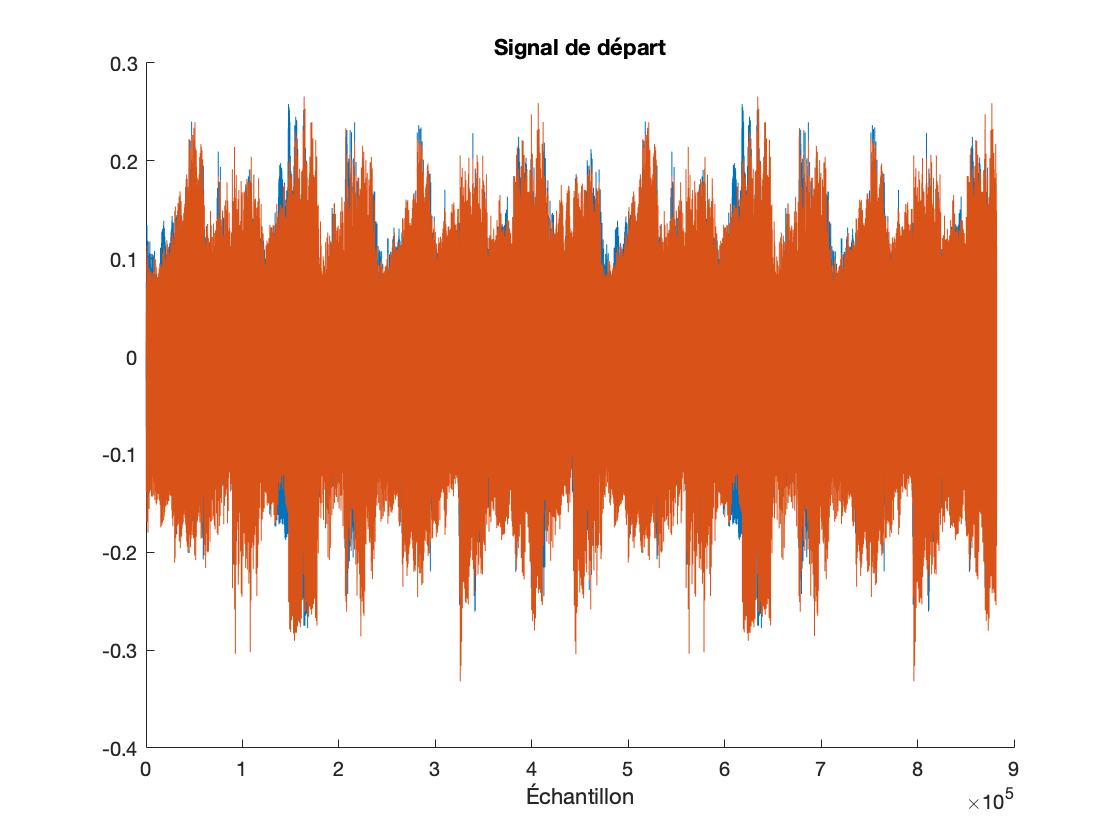

[~,Fs] = audioread('pia_vio_bas.wav');
samples = [1,20*Fs];     %Je ne prends que les 10 premières secondes, sinon mon ordi est à la rue
clear y Fs
[x,Fs] = audioread('pia_vio_bas.wav',samples);

%Ordre des instrument : gauche mid droite donné dans le nom du fichier

m =2;   %Nombre de canaux
x1 = x(:,1);  %J'ai séparé les deux signaux, parce que Stereo
x2 = x(:,2);
%x1 = x1(1:4:end);
%x2 = x2(1:4:end);

%x = [x1, x2];

%Nombre d'éléments du signal
T = length(x);
%Durée d'observation, en secondes
Tobs = T / Fs;
%Plot
figure;
title('Signal de départ')
xlabel("Échantillon")
hold on;
plot(x1);
plot(x2)
hold off

Dans la section suivante, j'importe les différentes sources individuelles pour pouvoir les comparer à nos solutions potentielles


[s1, ~] = audioread("bass.wav", samples);
[s2, ~] = audioread("chords.wav", samples);
[s3, ~] = audioread("arpeges.wav", samples);
%Ce sont nos sources au départ, ça peut servir


s1 = s1(:,1);
s2 = s2(:,1);
s3 = s3(:,1);
%Je ne prends qu'un canal
        
%         
% S(1,:)=s1;
% S(2,:)=s2;
% S(3,:)=s3;  %On génère notre matrice permettant d'avoir une fenetre avec le code tout fait
% 



## Étape 2 - Parcimonier !

Je vais maintenant transformer ce sur quoi je travaille. En effet, je vais passer dans un autre domaine, et utiliser la ***modified discrete cosine transform, ***et la*** short-timed Fourier transform***

On qualifiera ces transformées de ***sparsifying linear transforms --> ***Elle vont, a fortiori, rendre nos données parcimonieuses. C'est afin de pouvoir comparer les méthodes que nous utiliserons deux transformations.

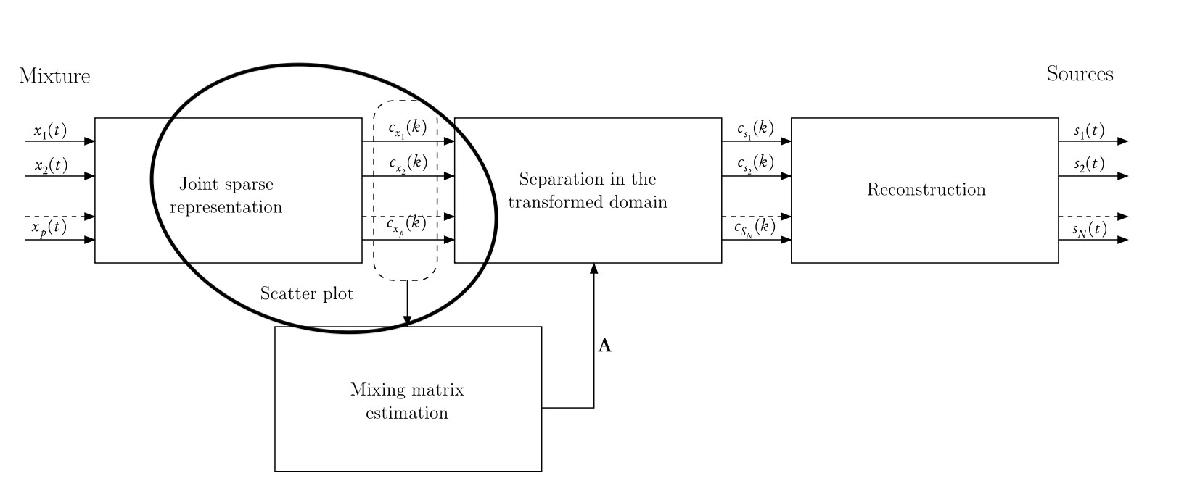

En effet, dans les faits les signaux audio sont tout sauf parcimonieux à la base. 

C'est un problème à dominantes multiples (Les sources sont actives simultanément), ce qui rend la chose bien plus difficile.  

Pour appliquer nos transformées, nous devons définir des fenêtres sur lesquelles appliquer nos transformations. 

win_size = 1024;  %On définit leur tailles en nombres d'éléments

% On peut déjà commencer par une fenêtre rectangulaire. Simple, efficace
win = rectwin(win_size);


*La section suivante contient le code utilisant la ****MDCT***

cx1 = mdct(x1,win);             %Un canal
cx2 = mdct(x2, win);            %l'autre
coeff_size = size(cx1);  %Permet de se rendre compte que mdct renvoie une matrice ! 



Affichage de nos coefficients sous la forme d'un spectrogramme

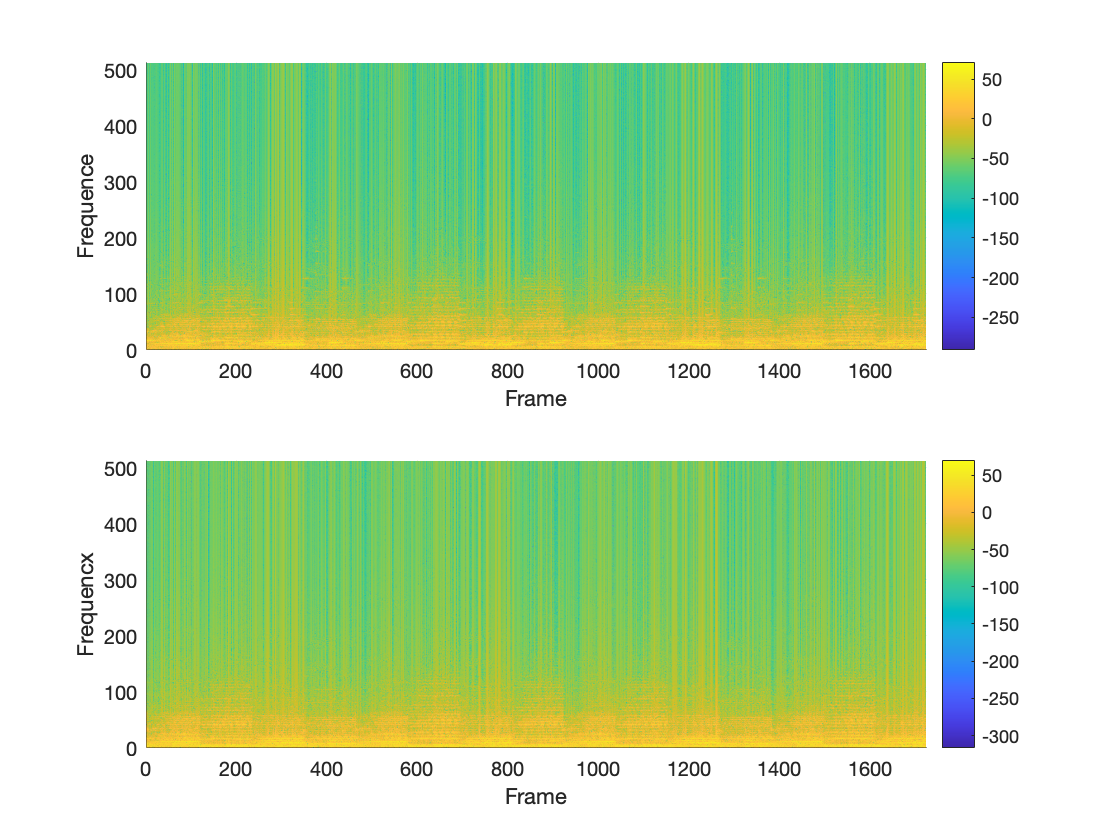

subplot(2,1,1);
surf(20*log10(cx1.^2),'EdgeColor','none'); %plot une surface
view([0 90])
xlabel('Frame')
ylabel('Frequence')
axis([0 size(cx1,2) 0 size(cx1,1)])
colorbar
subplot(2,1,2);
surf(20*log10(cx2.^2),'EdgeColor','none'); %plot une surface
view([0 90])
xlabel('Frame')
ylabel('Frequencx')
axis([0 size(cx2,2) 0 size(cx2,1)])
colorbar

Cette cellule ci utilise la** STFT** (short-timed Fourier Transform), avec la fonction spectrogram() déjà implémentée .

[S1,F1,T1] = spectrogram(x1,win,win_size/2);   %STFT
[S2,F2,T2] = spectrogram(x2,win,win_size/2);    %STFT 


S = [S1(:) S2(:)];      %Vectorisation, puis concaténations des coefficients de chaque canal



Nous avons donc calculer nos coefficients associés à nos deux transformations. 

Tracer l'histogramme permet de voir si on a une distribution parcimonieuse.

 cf 10.3 du Chap 10 - Handbook blind source separation

Ici, nos coefficients de transformée sont complexes, j'affiche donc la valeur absolue de ces coefficients.

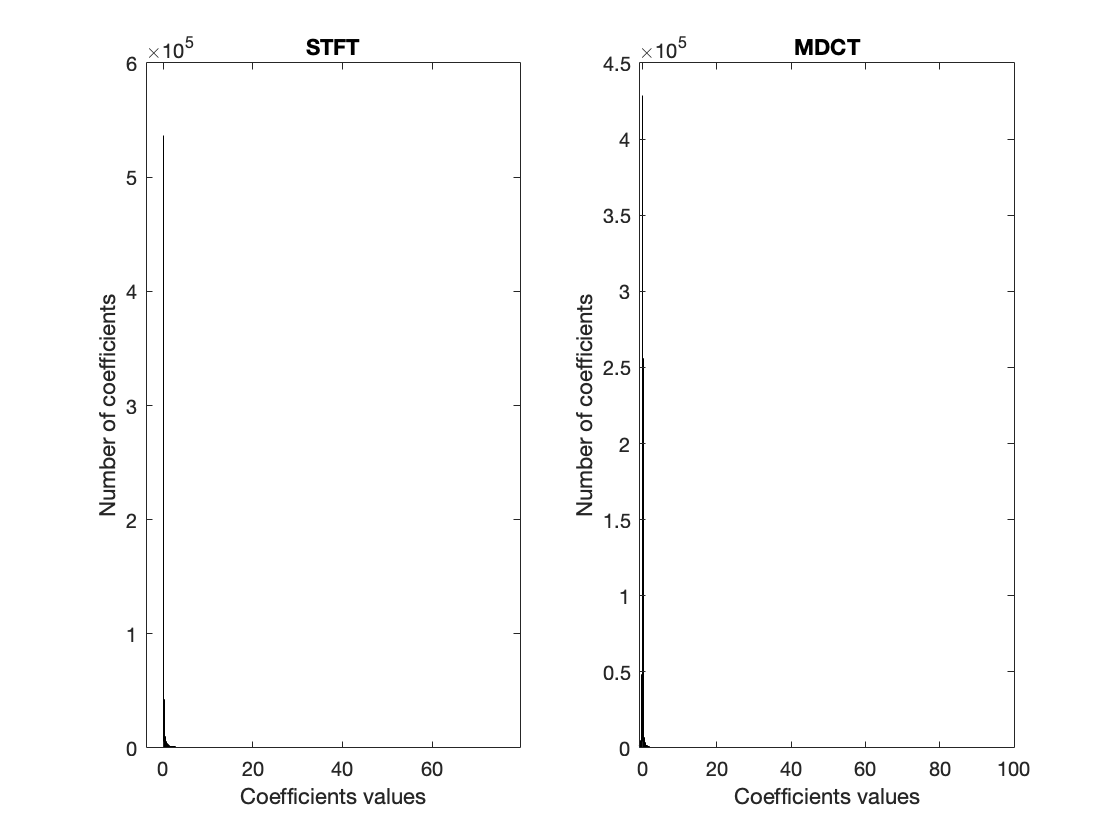

figure;
subplot(121)
histogram(abs(S1),1000);    %Assez peu représentatif, on ne se rend pas bien compte de ce qu'il se passe
                            % de ce qu'il se passe dans voisinage plus
                            % petit de 0
title('STFT')
xlabel('Coefficients values')
ylabel('Number of coefficients')
subplot(122)                           
histogram(cx1,1000);     
title('MDCT')
xlabel('Coefficients values')
ylabel('Number of coefficients')
xlim([-1 100])  

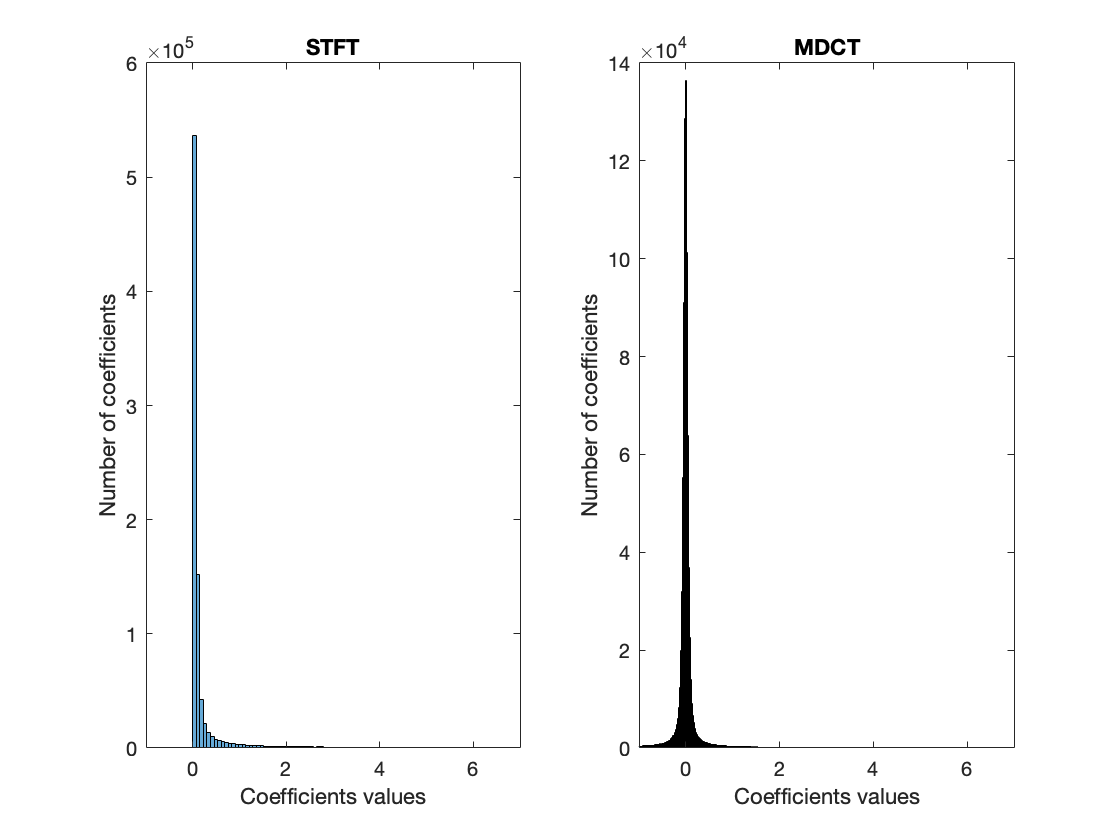




figure;  %Pour regarder de plus près autour de 0
subplot(121)
histogram(abs(S1),1000);
title('STFT')
xlabel('Coefficients values')
ylabel('Number of coefficients')
xlim([-1 7])

subplot(122)
histogram(cx1,5000);
title('MDCT')
xlabel('Coefficients values')
ylabel('Number of coefficients')
xlim([-1 7])

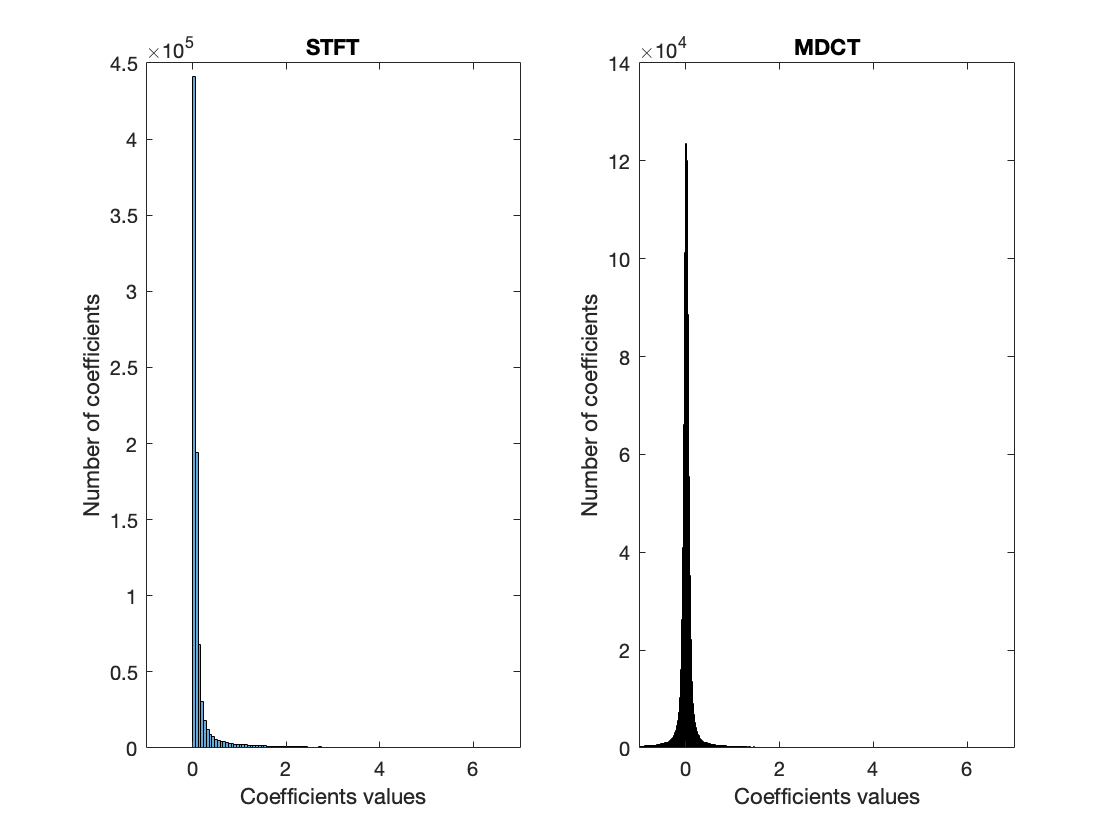


figure;  %Pour regarder de plus près autour de 0
subplot(121)
histogram(abs(S2),1000);
title('STFT')
xlabel('Coefficients values')
ylabel('Number of coefficients')
xlim([-1 7])

subplot(122)
histogram(cx2,5000);
title('MDCT')
xlabel('Coefficients values')
ylabel('Number of coefficients')
xlim([-1 7])

**Étant donné qu'on a pic pour des valeurs très petites, on peut se dire que c'est le cas : **

**on a plein de valeurs considérées comme quasi-nulles. **

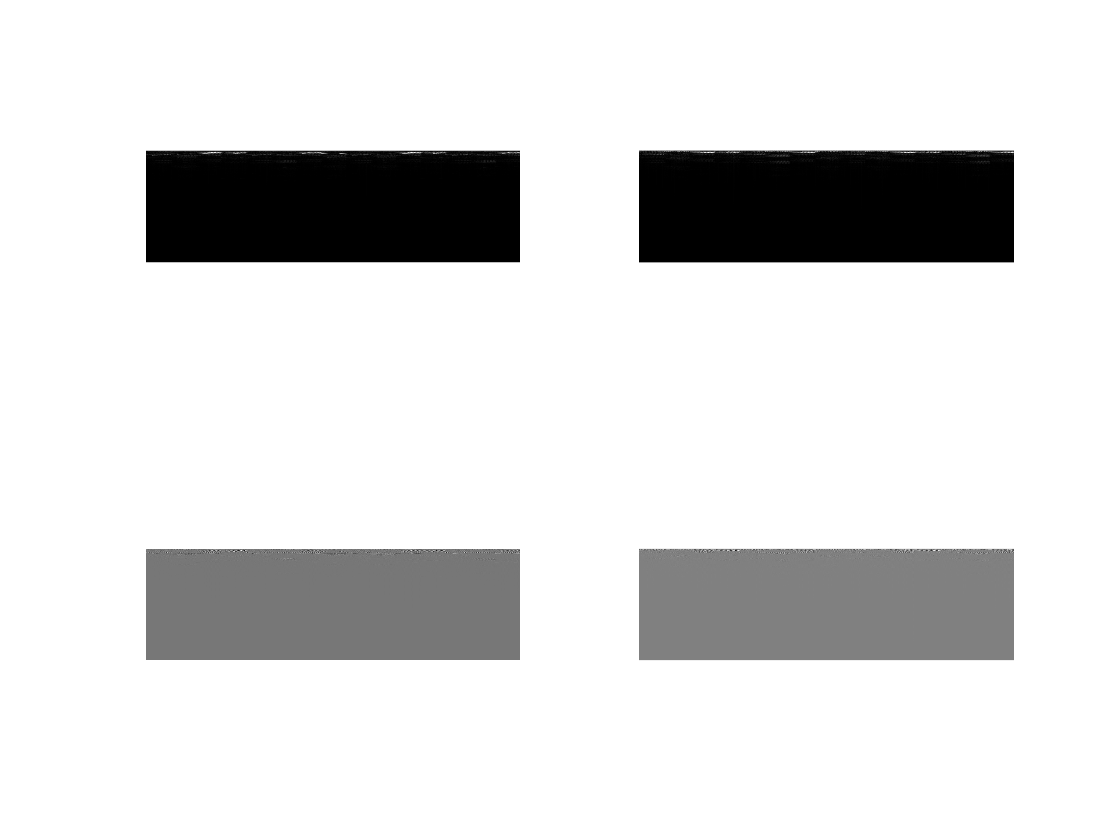


%Je trouvais sympa, pour montrer la parcimonie, de visionner des
%images.

figure;
title("Illustration de la parcimonie dans nos coefficients")

ax1 = subplot(2,2,1);
M1 = mat2gray(abs(S1));
title("STFT canal 1")
imshow(M1);

ax2 = subplot(2,2,2);
M2 = mat2gray(abs(S2));
title("STFT canal 2")
imshow(M2);

ax3 = subplot(2,2,3);
xlabel("MDCT canal 1")
M3 = mat2gray(cx1);
imshow(M3);

ax4 = subplot(2,2,4);
title("MDCT canal 2")
M4 = mat2gray(cx2);
imshow(M4);

A présent, visualisons nos Scatter plot, et voyons s'ils ont l'air cohérents !

Les scatter plot correspondent aux nuages de points (c1(k), c2(k)) avec 1<k<K

Ici, avec deux canaux, on a deux dimensions :) 

Nous nous attendons à voir des directions distinctes : 

***MDCT***

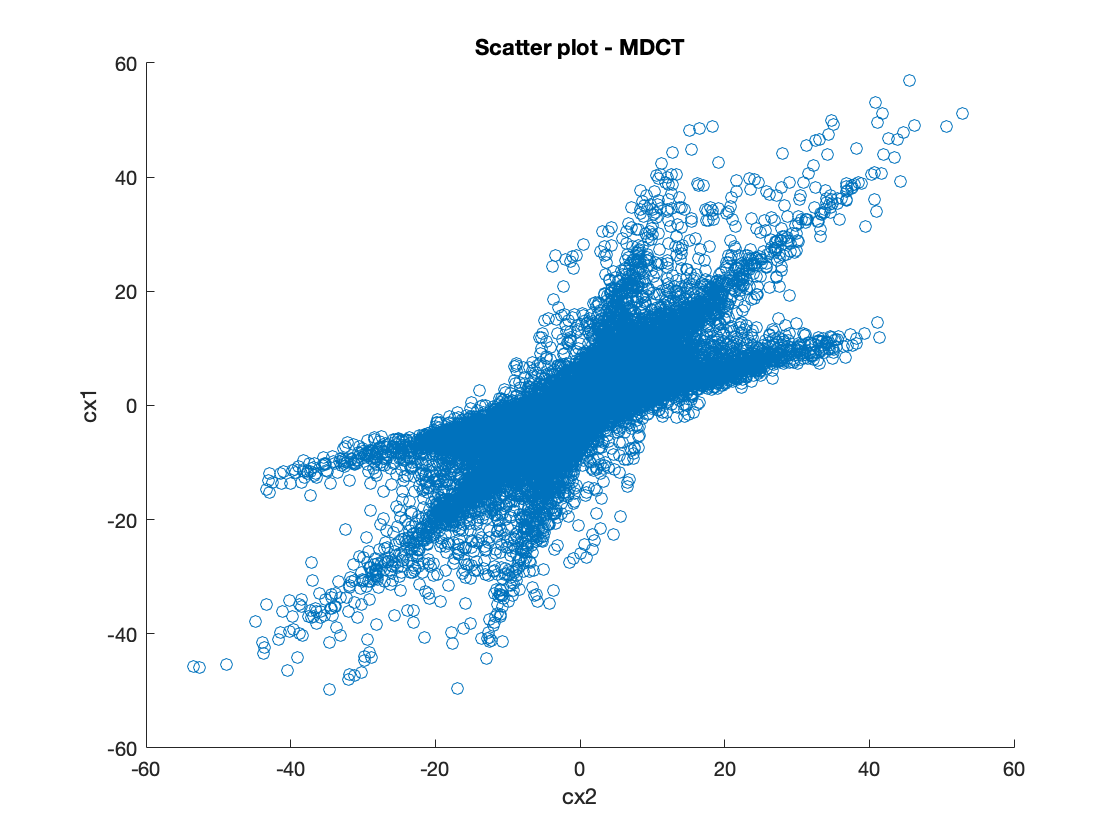

c1 = cx1(:); 
c2 = cx2(:);    % Vectorisation

figure;
scatter(c2,c1);
title("Scatter plot - MDCT")
xlabel('cx2')
ylabel('cx1')

***STFT***

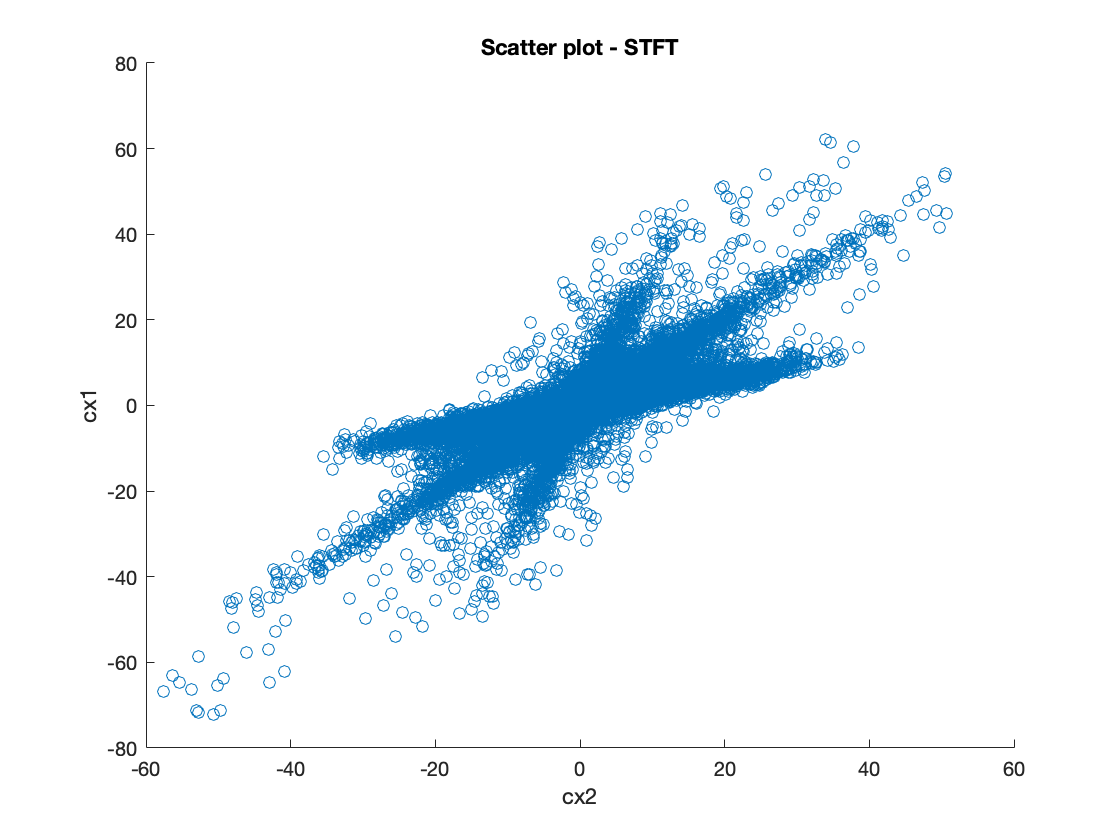

figure;
scatter(real(S2(:)), real(S1(:)));     %rappel : nos coefficients de STFT sont complexes!
title("Scatter plot - STFT")
xlabel('cx2')
ylabel('cx1')

Nous voyons bien ici trois directions ! 

Dans l'idée, on se rend compte que les directions principales sont moins dispersées avec la STFT.

## Étape 3 - Estimation de la *Mixing Matrix*

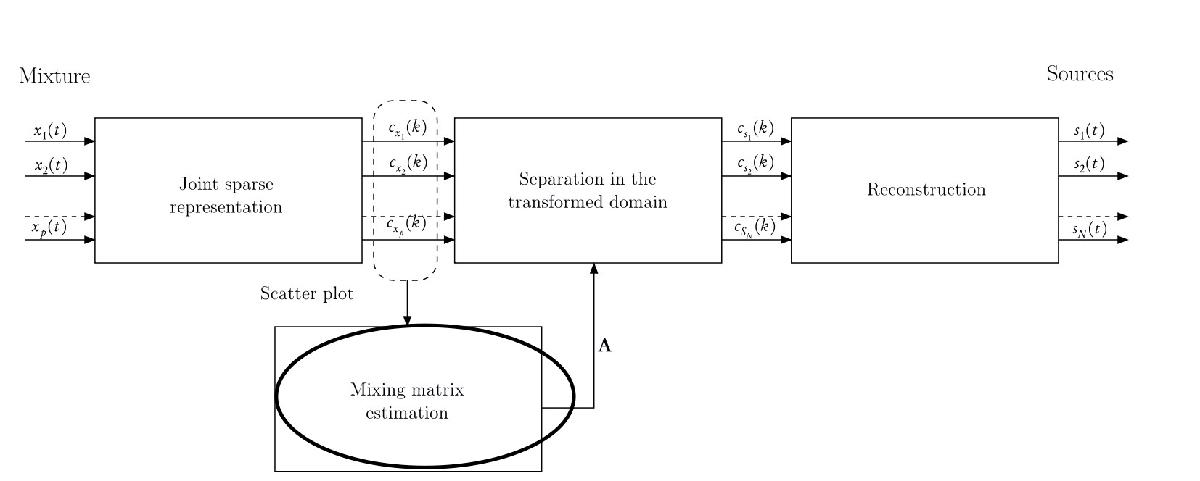

La matrice de mélange, que l'on notera A, représente le mélange de nos différentes sources, qui composent notre signal final. 

Pour coller aux notations du Handbook, je vais construire la matrice Cx, qui correspond à : 

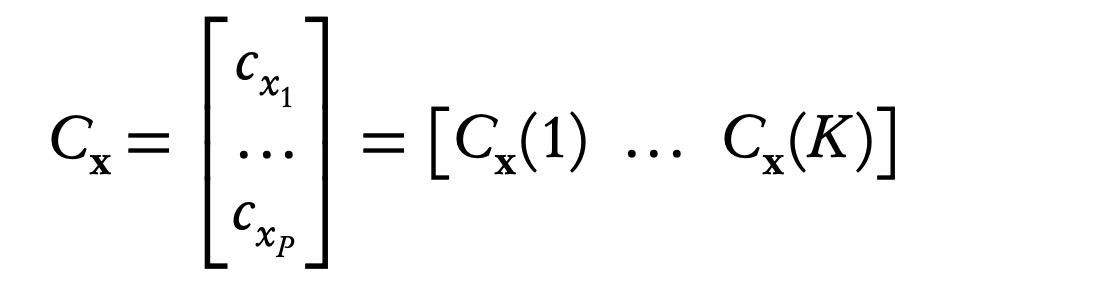

cf équation 10.12

Le but est d'estimer la n-ième colonne de A, et la direction qui correspond.

***STFT***

Cx_stft = [abs(S1(:))' ;  abs(S2(:))'];   % Pas certain que je doive utiliser le module, je perd une partie de l'information...
Csize_stft = size(Cx_stft);
rho = zeros([1 Csize_stft(2)]);
theta = zeros([1 Csize_stft(2)]);


for k = 1:length(Cx_stft)
    theta(k) = atan(Cx_stft(2,k)/Cx_stft(1,k));
    rho(k) = sqrt(abs(Cx_stft(2,k))^2  + abs(Cx_stft(1,k))^2);
    if theta(k)<0
        theta(k) = theta(k) + pi;
        rho(k) = -sqrt(abs(Cx_stft(2,k))^2  + abs(Cx_stft(1,k))^2);
    end           
end

***MDCT***

Cx_mdct = [cx1(:)' ;  cx2(:)'];   % Pas certain que je doive utiliser le module, je perd une partie de l'information...
Csize_mdct = size(Cx_mdct);
rho_mdct = zeros([1 Csize_mdct(2)]);
theta_mdct = zeros([1 Csize_mdct(2)]);


for k = 1:length(Cx_mdct)
    theta_mdct(k) = atan(Cx_mdct(2,k)/Cx_mdct(1,k));
    rho_mdct(k) = sqrt(abs(Cx_mdct(2,k))^2  + abs(Cx_mdct(1,k))^2);
    if theta_mdct(k)<0
        theta_mdct(k) = theta_mdct(k) + pi;
        rho_mdct(k) = -sqrt(abs(Cx_mdct(2,k))^2  + abs(Cx_mdct(1,k))^2);
    end           
end

***Affichages des directions trouvées***

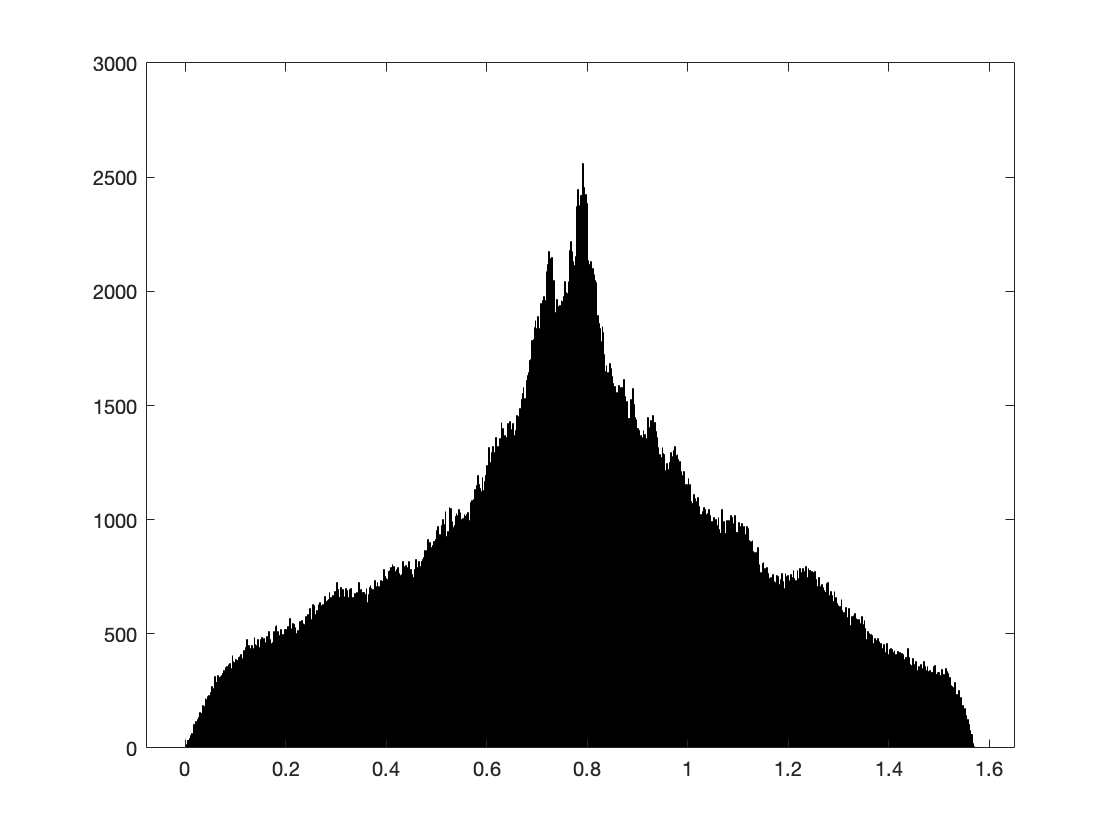

figure;
histogram(theta,1000);

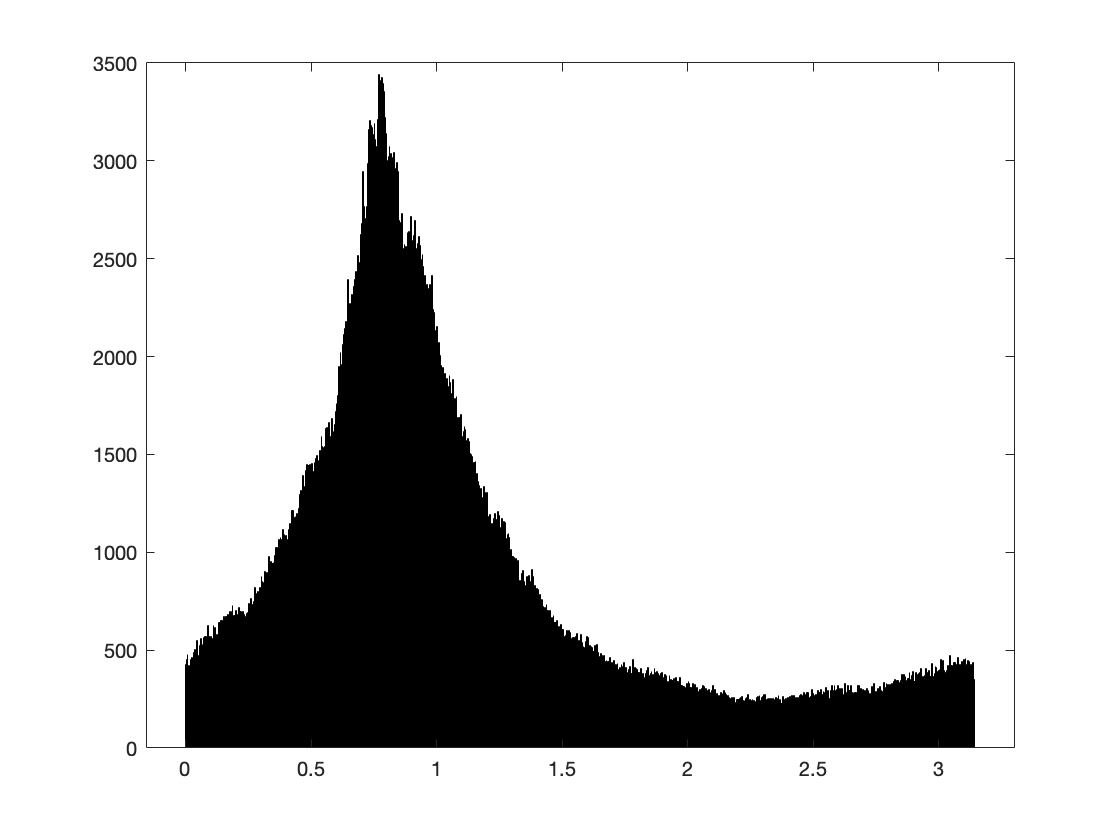

figure;
histogram(theta_mdct,1000);

Fichtre, nous n'allons pas aller bien loin avec ça ! 

Heureusement, le handbook nous propose d'utiliser un histogramme pondéré, plutôt qu'un histogramme sorti du chapeau en espérant trouver des directions.

On va donc définir notre fonction de lissage (qui sera exponentielle), et l'appliquer à nos valeurs de thêta.  cf équation 10.35 remaniée pour pas utiliser Parzen de la Vallée Poussin

smoothing_win = rectwin(win_size);  
theta_l = linspace(0,pi,win_size+1);
H = zeros(1,win_size+1);
for l =1:win_size+1
    for k = 1:Csize_stft(2)
        %H(l) = H(l) + rho(k)*smoothing_win(floor(win_size*(theta_l(l)-theta(k))));
        H(l) = H(l) + rho(k) * exp(-((theta_l(l)-theta(k))^2) /0.0001);
    end
end

Afficher le module de nos points en fonction de leur module permet déjà de se rendre compte qu'il existe 3 directions.

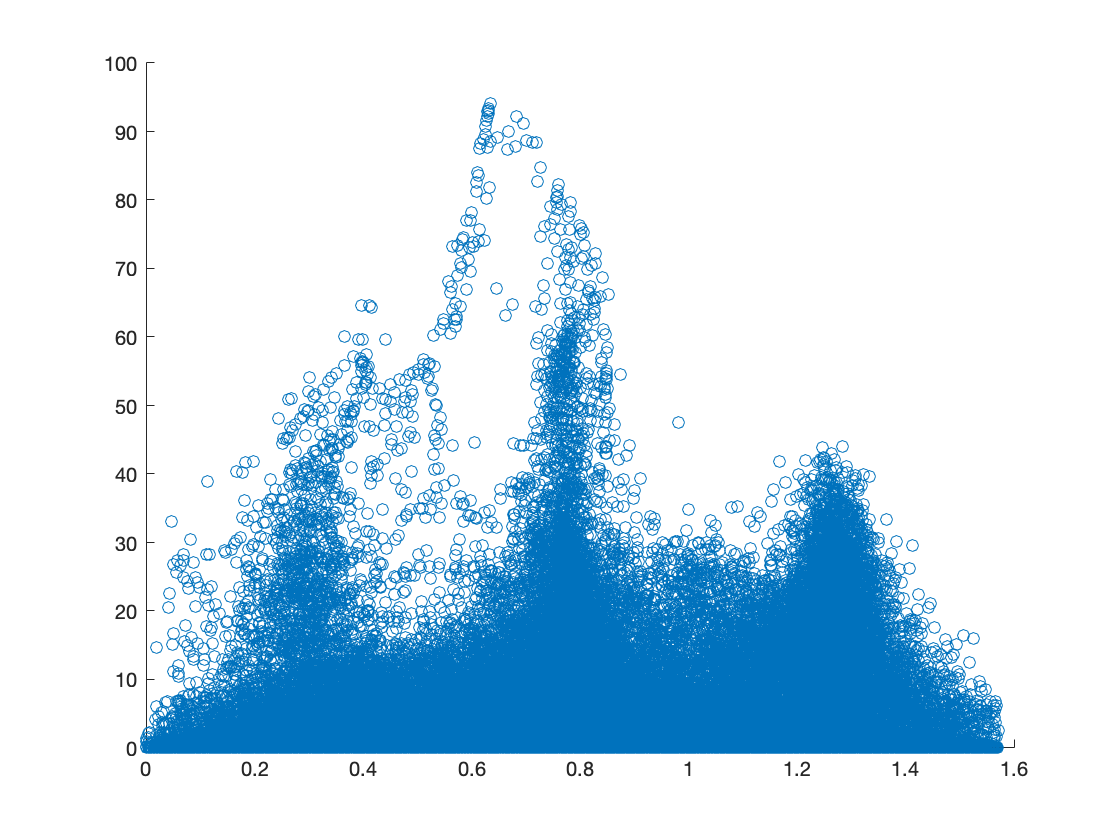

figure;
scatter(theta,rho)

On voit bien trois directions qui se démarquent. C'est sympa ! 

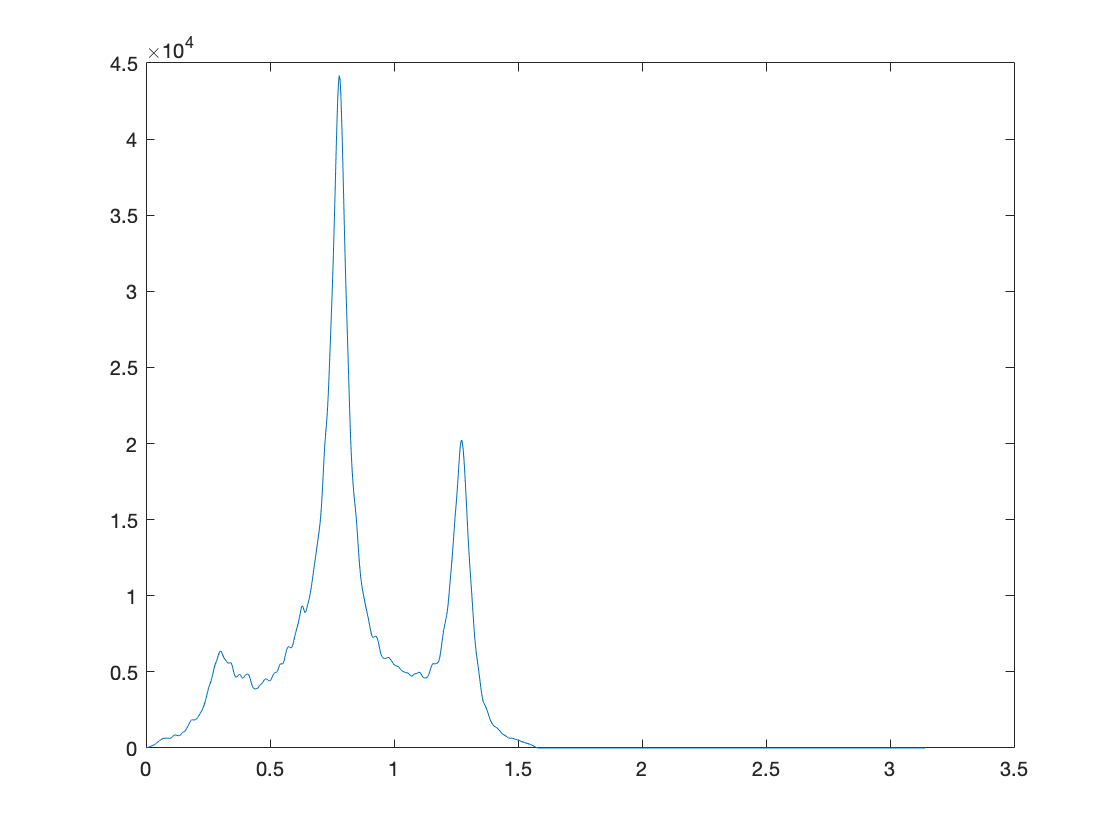

figure;
plot(theta_l,H)

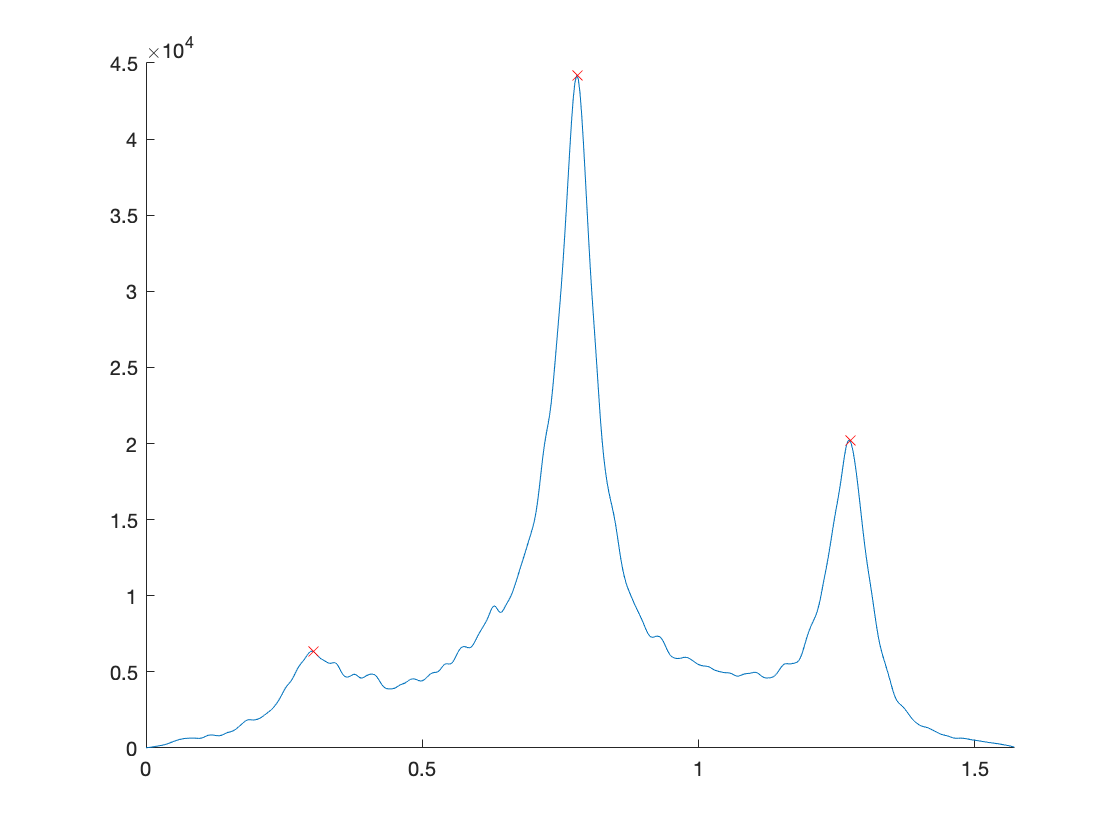

[peaks, locs] = findpeaks(H,"MinPeakWidth",15);
locs = pi*locs ./ 1025;

figure;
hold on
plot(theta_l,H)
plot(locs,peaks,'x',"Color",'r')
hold off
xlim([0, pi/2])

Youpi, des pics et des directions associées ! 

On construit donc notre matrice A. Attention ! La matrice A présentée dans le handbook concerne la MDCT, il faut donc la remanier pour la STFT

***MDCT***

%faire un findpeaks , excellent

A1_mdct = [cos(locs(1)) sin(locs(1))]';
A2_mdct = [cos(locs(2)) sin(locs(2))]';
A3_mdct = [cos(locs(3)) sin(locs(3))]';  %marche avec la mdct, il faudrait des exp pour la STFT

A_mdct= [A1_mdct A2_mdct A3_mdct];

***STFT***

A1_stft = [exp(1i * locs(1)) exp(-1i*locs(1))]';
A2_stft = [exp(1i * locs(2)) exp(-1i*locs(2))]';
A3_stft = [exp(1i * locs(3)) exp(-1i*locs(3))]';  %marche avec la mdct, il faudrait des exp pour la STFT

A_stft= [A1_stft A2_stft A3_stft];

## Étape 4 - Séparation en composantes indépendantes

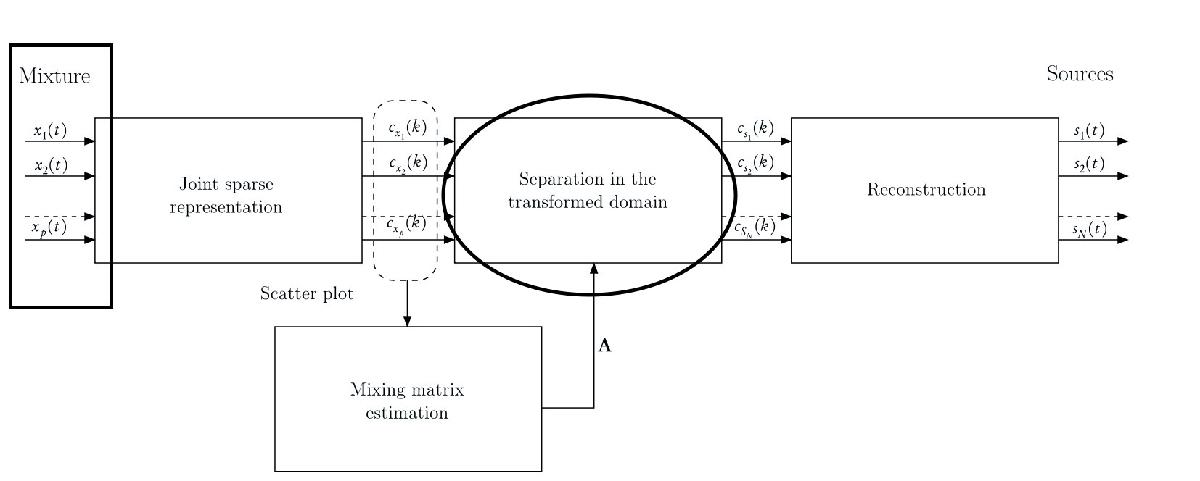

Premier essai avec juste la pseudo_inverse de A

***MDCT***

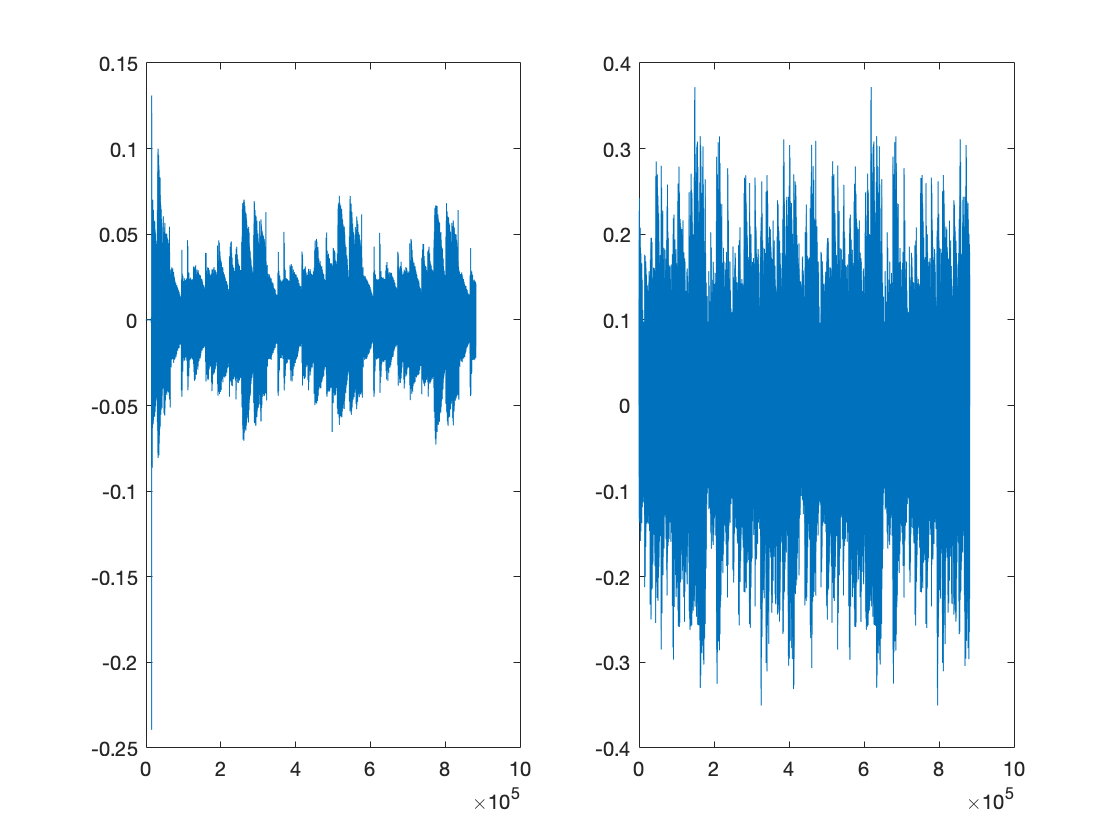

Cs =  pinv(A_mdct)*Cx_mdct;
Cs1 = reshape(Cs(1,:),512,1724);
Cs2 = reshape(Cs(2,:),512,1724);
Cs3= reshape(Cs(3,:),512,1724);

s1_mdct = imdct(Cs1,rectwin(win_size));
s2_mdct = imdct(Cs2,rectwin(win_size));
s3_mdct = imdct(Cs2,rectwin(win_size));


figure;
subplot(121)
plot(s1)
subplot(122)
plot(s1_mdct)

## ***STFT***